clear all
load("geo_file2.mat")
data = double(data');

SI = 2000 * 1e-6;
fs = 1/SI;


lpFilt = designfilt('lowpassfir', 'FilterOrder', 50, 'PassbandFrequency', 30, ...
         'StopbandFrequency', 80, 'DesignMethod','ls', 'SampleRate', fs);
% fvtool(lpFilt)


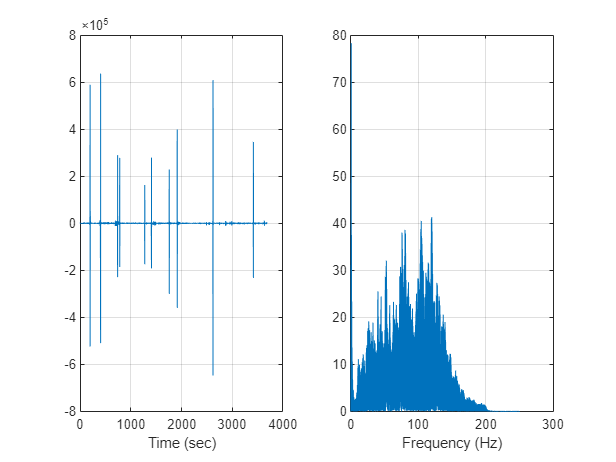

t = 0:SI:SI*(numel(data)-1);
filtered_data = filtfilt(lpFilt, data);

result_fft_raw = one_sided_fft_no_vrms(data, fs, 0);
result_fft_filtered = one_sided_fft_no_vrms(filtered_data, fs, 0);



figure;
subplot(121)
plot(t, data)
grid on
xlabel('Time (sec)')
subplot(122)
plot(result_fft_raw(:, 1), result_fft_raw(:, 2))
grid on
xlabel('Frequency (Hz)')

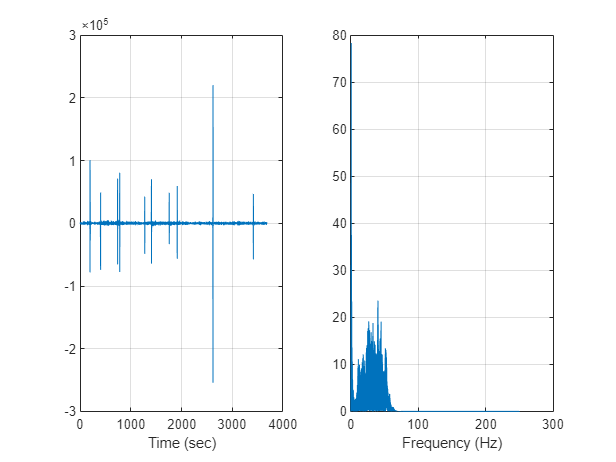


figure
subplot(121)
plot(t, filtered_data)
grid on
xlabel('Time (sec)')
subplot(122)
plot(result_fft_filtered(:, 1), result_fft_filtered(:, 2))
grid on
xlabel('Frequency (Hz)')

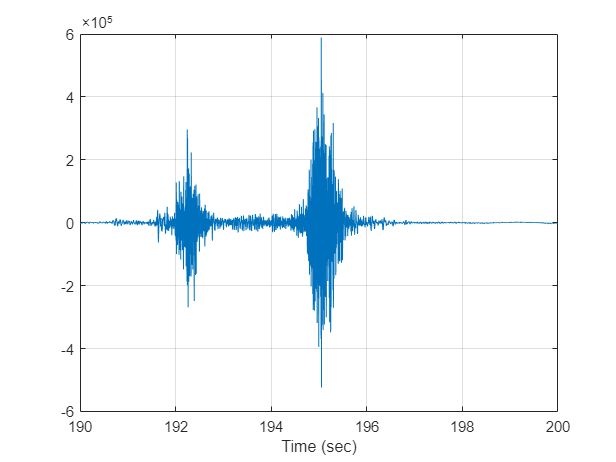


figure;
plot(t, data)
grid on
xlabel('Time (sec)')
xlim([190 200])

clear data


fs = 500

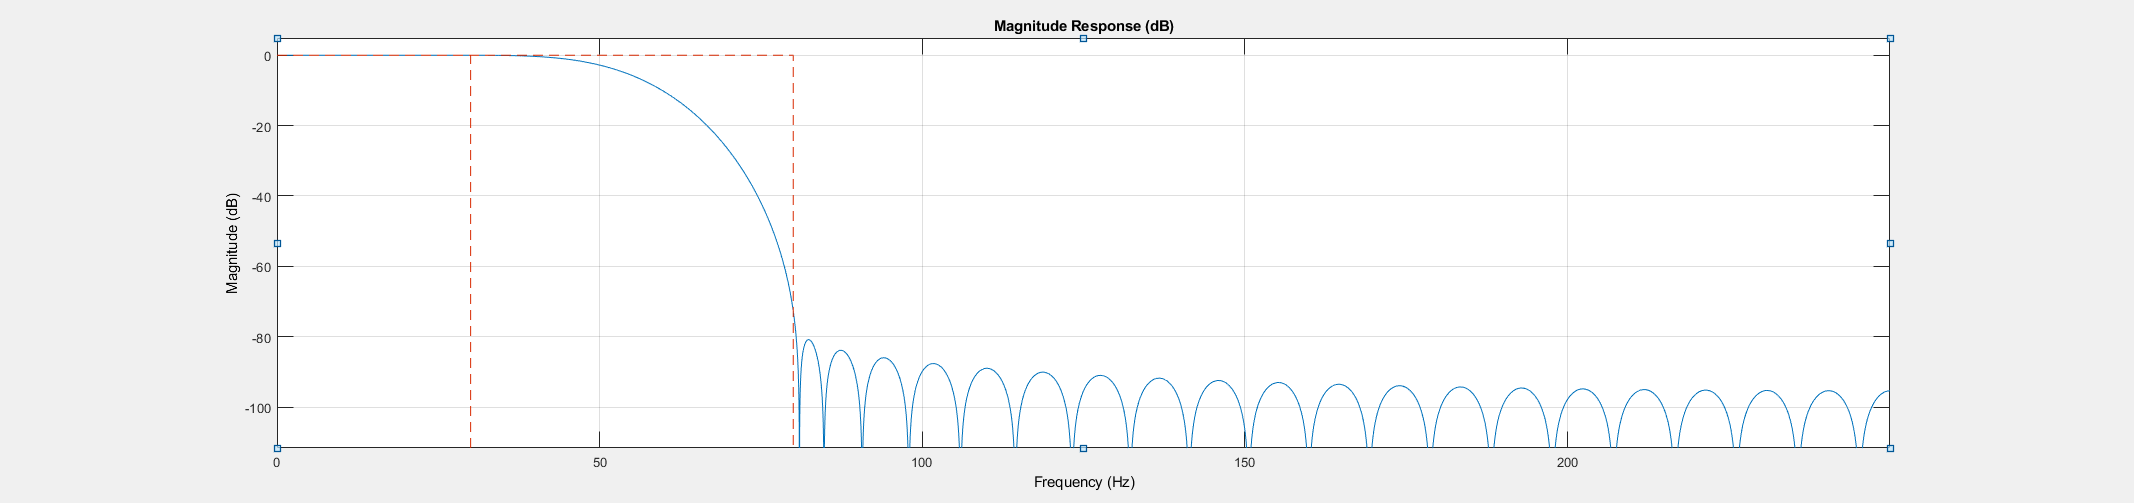


% 
% bpFilt = designfilt('lowpassfir','FilterOrder',800, ...
%         'DesignMethod', 'ls', ...
%         'StopbandFrequency1', stop_pass_range(1), 'PassbandFrequency1', band_pass_range(1), ...
%         'StopbandFrequency2', stop_pass_range(2), 'PassbandFrequency2', band_pass_range(2), ...
%         'StopbandWeight1', 10, 'PassbandWeight', 10, 'StopbandWeight2', 3, ...
%         'SampleRate',1/dt);




result_fft = one_sided_fft_no_vrms(new_data(45000:90000), fs, 0);

result_fft = 	1.0e+05 *

         0    0.1193
    0.0000    0.3515
    0.0000    0.1414
    0.0000    0.0290
    0.0000    0.2685
    0.0000    0.0874
    0.0000    0.0827
    0.0000    0.1110
    0.0000    0.2741
    0.0000    0.1173


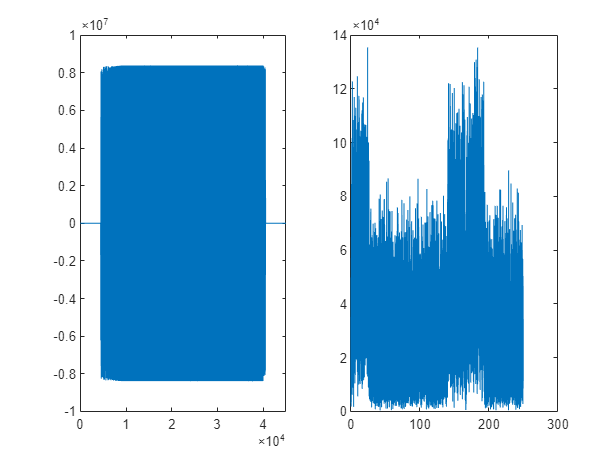


figure;
subplot(121)
plot(new_data(45000:90000))
subplot(122)
plot(result_fft(:, 1), result_fft(:, 2))

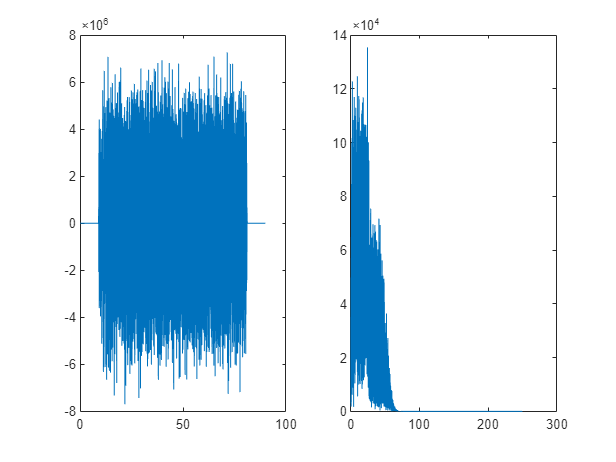

t = 0:SI:SI*(numel(filtered_data)-1);
figure;
subplot(121)
plot(t, filtered_data)
subplot(122)

result_fft = one_sided_fft_no_vrms(filtered_data, fs, 0);
plot(result_fft(:, 1), result_fft(:, 2))